# Applying Edge Detection

Edge detection is a part of image processing that is often used to prepare images for computer vision and deep learning applications.  For example, detecting the edges of objects enables robotic manipulators to locate the objects in space.  The neural network layers in deep learning applications match patterns of edges to known examples to identify faces and letters.

This reading explores some of the different options and parameters of the `edge` function, along with other related functions.

## Simple Gradient Methods

The Sobel, Prewitt, Roberts methods are simple gradient methods.  The Sobel method was described in detail previously, and the other methods consist of similar steps with different spatial filters.  

- The Sobel filter is equivalent to a centered, second-order finite difference approximation of the gradient.  

- The Pewitt filter is equivalent to a centered, first-order approximation.  

- The Roberts filter is an upwind first-order accurate approximation, oriented at a 45-degree angle.

### Optional Inputs

The `edge` function chooses a threshold in a manner similar to the `imbinarize` function.  You can specify your own threshold to select more or fewer edges.

These three methods allow more direct control over the gradient calculations.   By default, both the horizontal and vertical gradients are  computed and combined to determine the total image gradient.  You can specify to only use one of the two gradients to focus on horizontal or vertical edges.  Note that the Roberts filter computes gradients at 45 and 135 degrees relative to the horizontal.

You can also use the "`nothinning"` option to prevent edge from reducing the edges to a single pixel.

### Optional Outputs

These methods can return not only the chosen threshold, but the individual gradients as well.

### Examples

Here are a few simple images to illustrate the flexibility of the `edge` function with the simple gradient methods.  Use the drop-down menu to try the edge function on different images with the simple gradient methods.  Remember, applying a Gaussian blur to the image before detecting edges helps remove background noise while preserving the stronger edges.

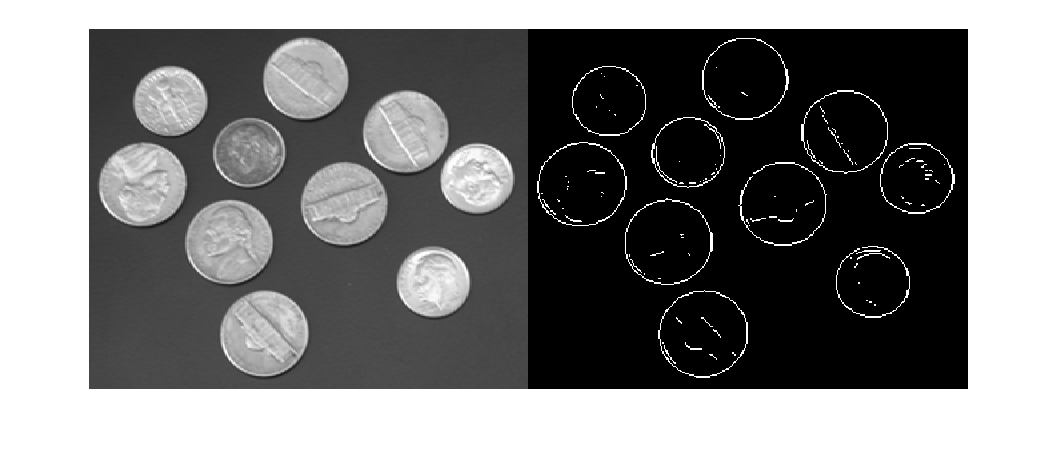

img = imread("coins.png");
imgFilt = imgaussfilt(img,0.5);
[imgEdge, threshOut, vertEdgeGrad, horzEdgeGrad] = edge(imgFilt,"sobel");
montage({img,imgEdge})

The computed threshold can be used as a starting point for selecting a custom threshold to keep more or fewer of the edges.

threshOut

threshOut = 0.0955

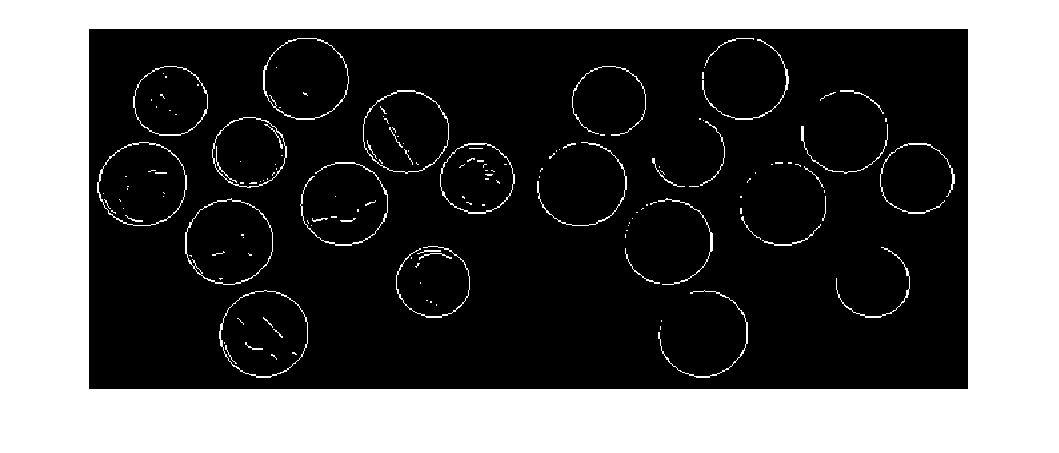

imgEdgeCustom = edge(imgFilt,"sobel",0.18);
montage({imgEdge, imgEdgeCustom})

Let's look at the returned gradients.  The x-direction gradient is used to determine the vertical edges and it returned in `vertEdgeGrad`.  The y-direction gradient is used to determine the horizontal edges and is returned in `horzEdgeGrad`.

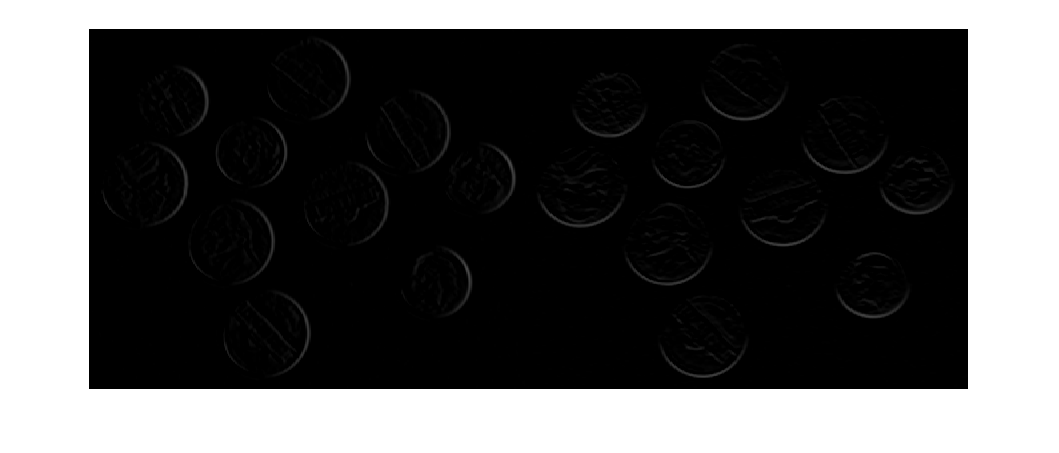

montage({vertEdgeGrad,horzEdgeGrad})

These don't seem to be showing as much detail as the output imgEdge in the montage above.  Looking at the Workspace, the data type for the gradients is `single`.  This means the values can be positive or negative, corresponding to positive and negative intensity gradients.  Use the `"DisplayRange"` option with a pair of empty brackets to view the full range of values in these images.

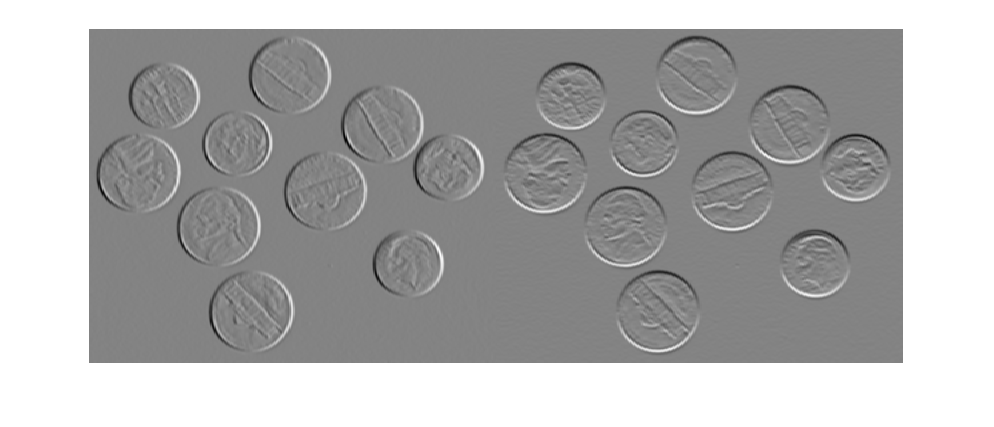

montage([vertEdgeGrad, horzEdgeGrad], "DisplayRange", [])

Use the 'nothinning' option to see the total gradient before the edge thinning.

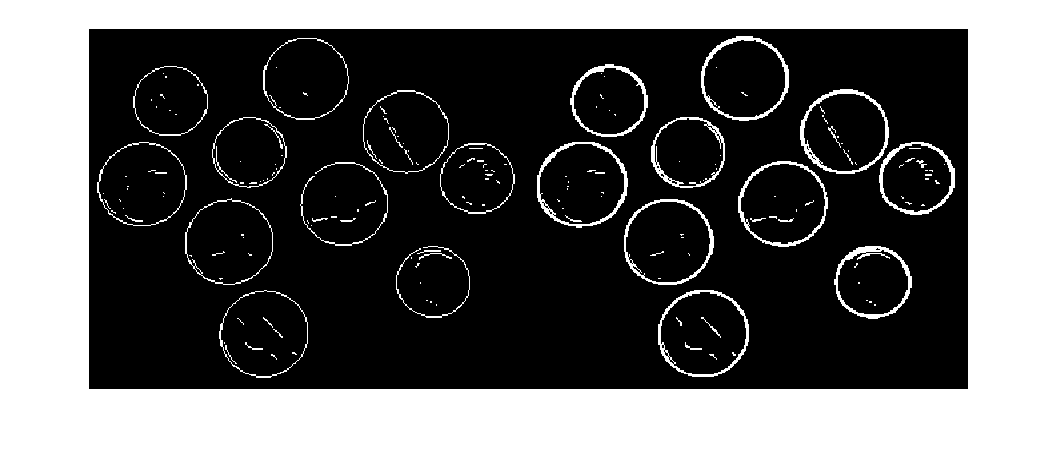

imgEdgeNoThinning = edge(imgFilt,"sobel","nothinning");
montage({imgEdge,imgEdgeNoThinning})

## Advanced Gradient Methods

The Canny and Laplacian of Gaussian (LoG) methods are more sophisticated than the previous methods.   There are fewer optional inputs available, and the individual gradients cannot be returned.  

The Canny method uses as pair of threshold values, while the LoG method uses a single threshold.  You can specify these if needed.  

Both of these methods contain a Gaussian filter as part of their computation.  The standard deviation, `sigma`, can be input after a threshold.  

In the code below, the threshold or thresholds can be placed in the brackets if desired, otherwise the threshold will be computed automatically.

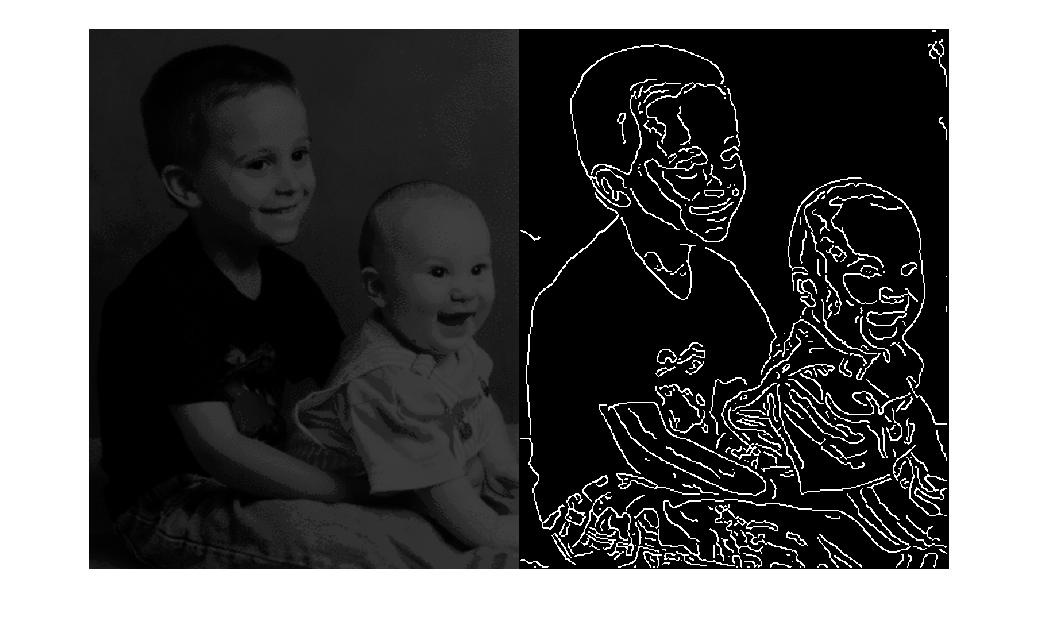

imgAdv = imread("kids.tif");
[imgAdvEdge, threshOut] = edge(imgAdv,"canny", [],1.414);
montage({imgAdv,imgAdvEdge})

The threshold chosen by the `edge` function is displayed below.

threshOut

threshOut =     0.0438    0.1094


## Application:  Detecting Crack Edges

The images in the crack data set contain many irregular edges.  Use the code below to explore how different methods and filters affect edge detection for these non-geometric shapes.

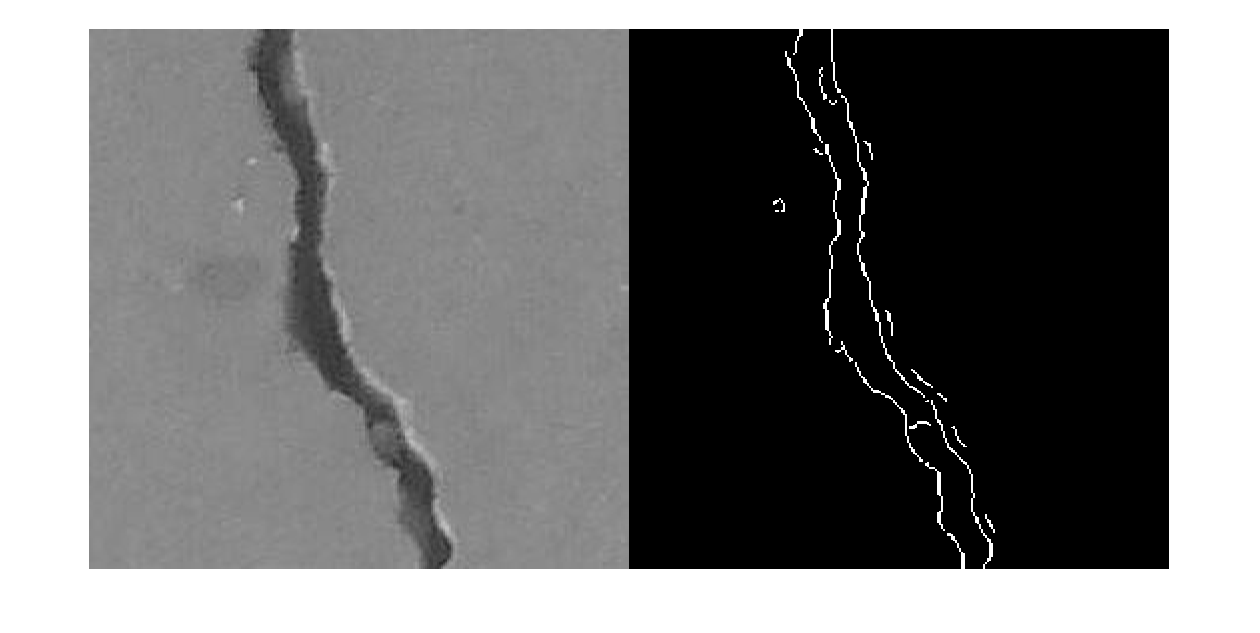

imgCrack = rgb2gray(imread("00001.jpg"));
imgFiltCrack = imgaussfilt(imgCrack,1.5);
imgEdgeCrack = edge(imgFiltCrack,"sobel");
montage({imgCrack,imgEdgeCrack})

## The `imfindcircles` and `viscircles` functions

Finding circles (or nearly circular objects) is such a common task in image processing that MATLAB has special functions just for this purpose:  `imfindcircles` and `viscircles`.  The `imfindcircles` function needs a lower and upper bound on the radii of the circles to be found.  It returns the centers and radii of the circles.

For large images, the `imfindcircles` function can be very slow.  There are two ways to increase it's performance.  The first is to restrict the range of possible radii.  You can use the Image Viewer Tool to measure a few of the circles in the image.  It's often easier to measure the diameter of the circle, so don't forget to halve these measurements to get the radii.

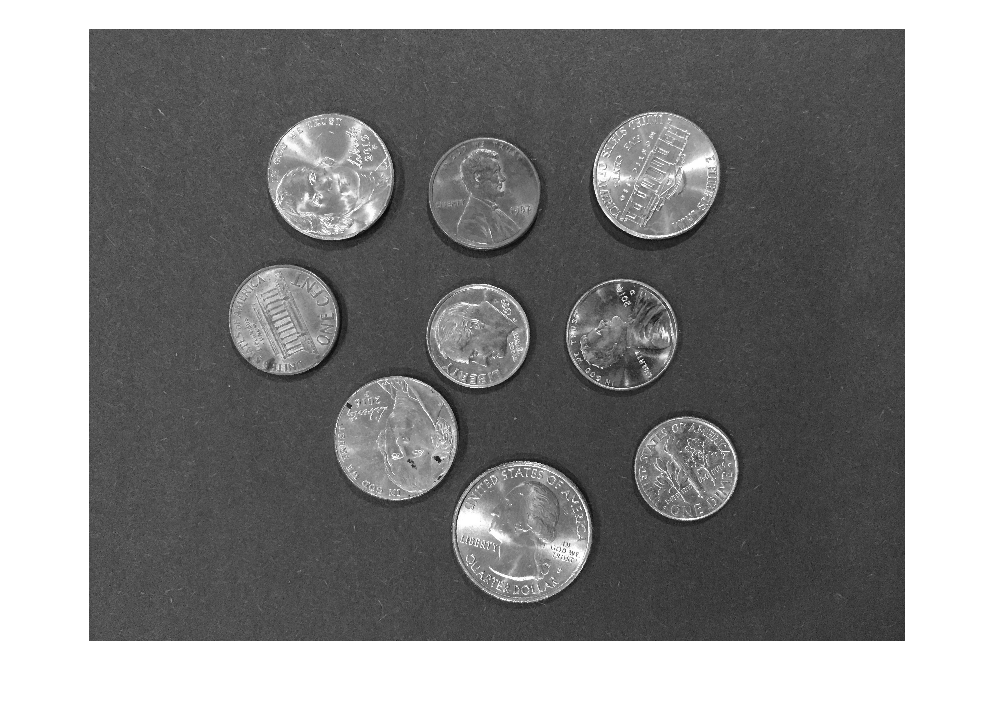

imgCirc = imread("coins3.jpg");
imshow(imgCirc)

Uncomment and run the lines below to launch the Image Viewer Tool with the coin image.  Replace the lower and upper bounds with more reasonable values.

% imtool(imgCirc)

lowerBound = 10;
upperBound = 20;
imgCirc = imgaussfilt(imgCirc,5);
[centers, radii] = imfindcircles(imgCirc,[lowerBound, upperBound])

centers = 	1.0e+03 *

    1.7472    2.2501
    2.1764    1.0544
    2.2214    0.4891
    2.0436    1.0531
    2.1112    1.1608
    1.9400    1.2168
    0.9690    0.3760
    0.8970    0.5939
    2.0537    0.5383
    1.1432    0.4746


radii =    15.9684
   12.3610
   11.0410
   12.6812
   13.9542
   12.5513
   11.6428
   15.5328
   12.3465
   11.1503


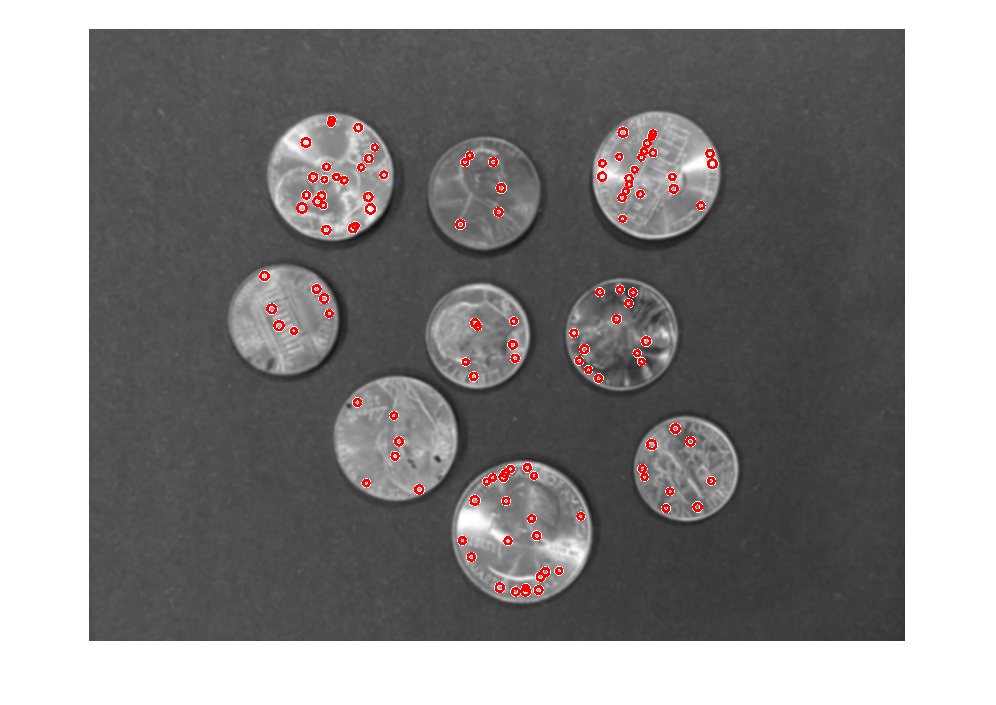

imshow(imgCirc)
viscircles(centers, radii);

Another way to improve the performance of the `imfindcircles` function is to resize the image.  High resolution cameras are now readily available, with many phones having megapixel resolutions.  You can significantly reduce the resolution and still have a clear image.

Let's start by reducing the image to 600 by 800 pixels, then looking for pixels with radii between 10 and 100 pixels.

imgCirc = imread("coins3.jpg");
imshow(imgCirc)

imgCirc = imresize(imgCirc,0.25);
imgCirc = imgaussfilt(imgCirc,3);
[centers, radii] = imfindcircles(imgCirc,[10,100])

centers =   598.1281  440.1298
  193.9853  291.0149
  307.2819  410.5063
  390.2877  306.5824
  431.9895  504.4890
  242.4044  147.0696
  566.4931  145.4215
  384.5084  493.8980
  395.5426  163.9463
  483.1238  524.5766


radii =    52.8257
   54.8460
   62.5482
   52.0350
   69.5760
   63.1252
   63.5311
   14.5300
   54.4044
   13.3834


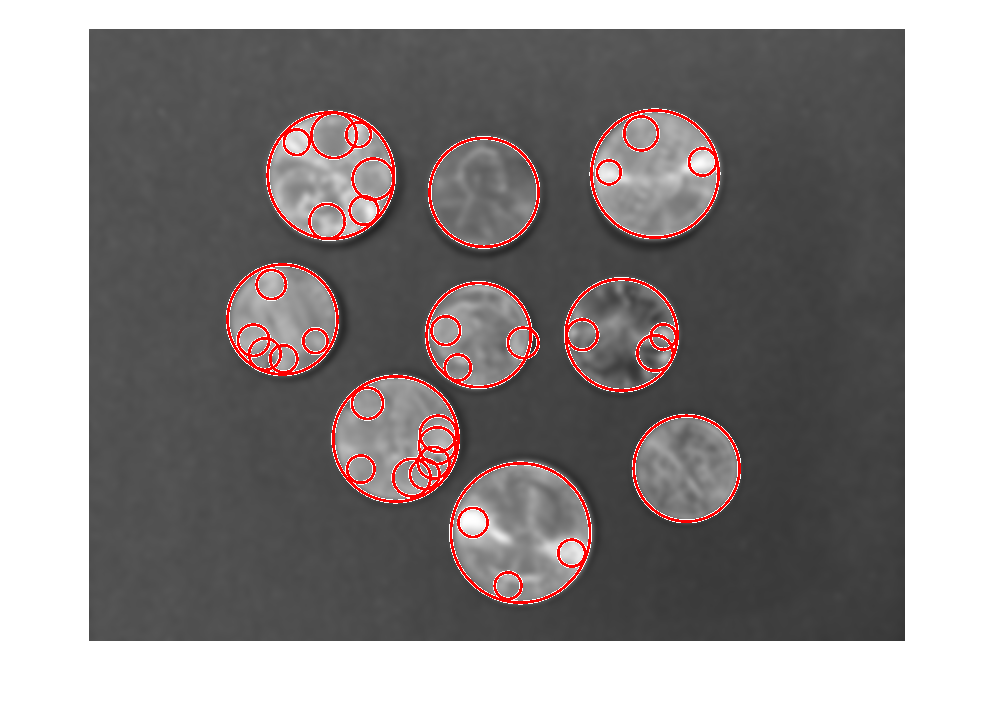

imshow(imgCirc)
viscircles(centers, radii);

That found a lot of circles inside the coins.  The distribution of the radii can help us sort the coin edges from these extra edges.

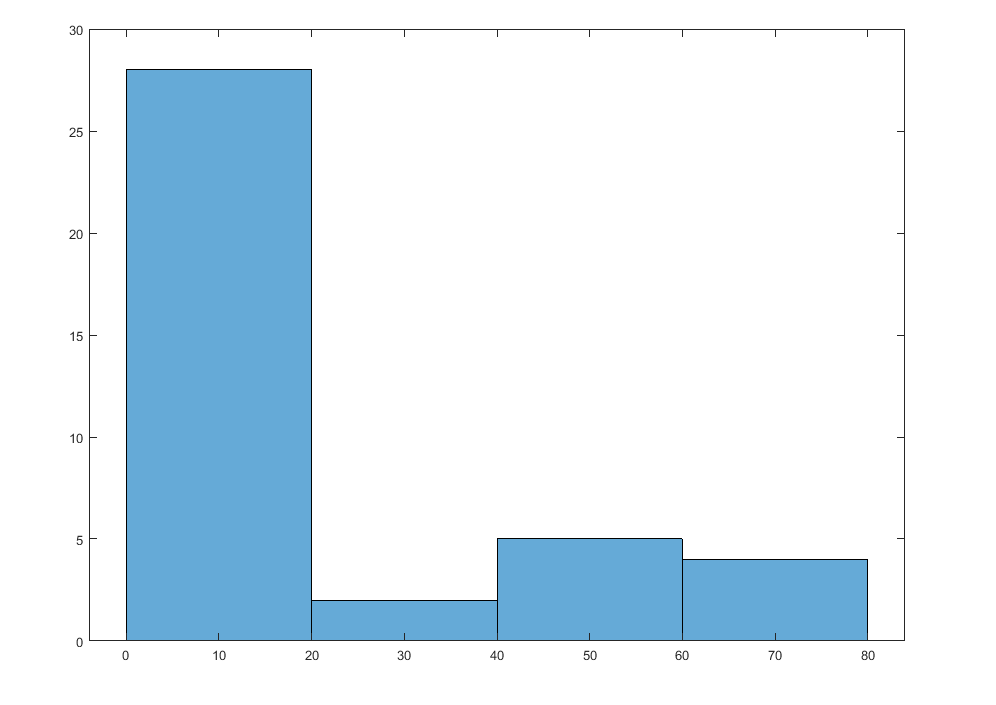

histogram(radii)

There are a lot of circles with radii smaller than 20 pixels.  These aren't likely to be the coin edges.  Let's change the bounds of the acceptable circles. 

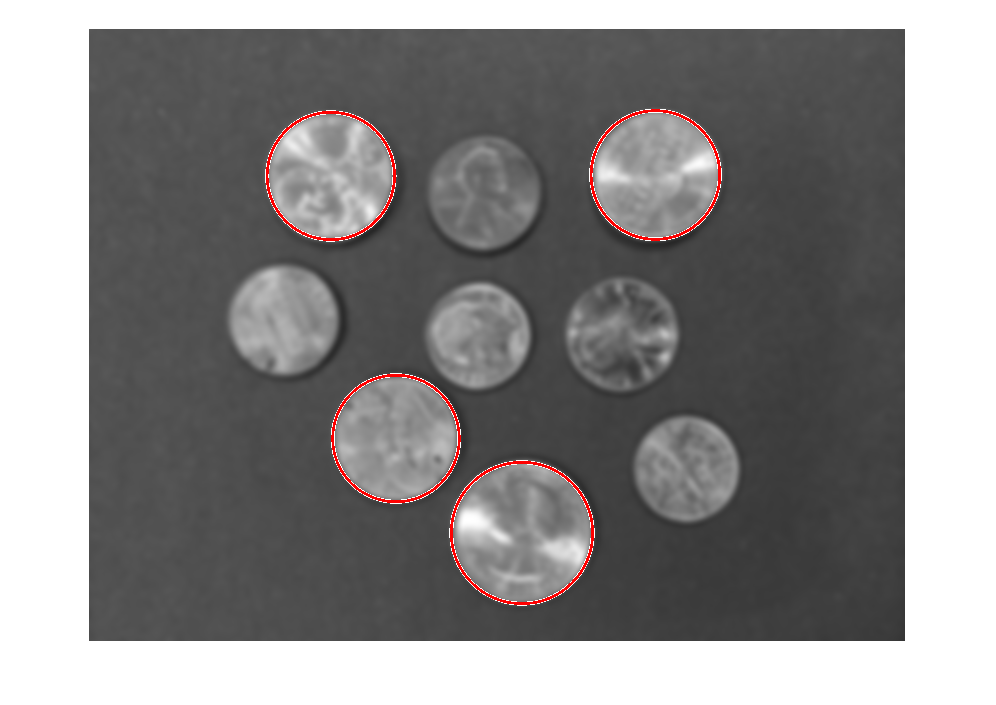

[centers, radii] = imfindcircles(imgCirc,[60,80]);
imshow(imgCirc)
viscircles(centers, radii);

Use the sliders to try to isolate individual types of coins.

*Copyright 2022 The MathWorks, Inc.*